clc;clear all;close all;
[cameraParams,intrinsics]=Traj_ArucoMarker_2_camCal()

cameraParams =   cameraParameters with properties:

   Camera Intrinsics
                         Intrinsics: [1×1 cameraIntrinsics]

   Camera Extrinsics
                  PatternExtrinsics: [18×1 rigidtform3d]

   Accuracy of Estimation
              MeanReprojectionError: 0.1352
                 ReprojectionErrors: [70×2×18 double]
                  ReprojectedPoints: [70×2×18 double]

   Calibration Settings
                        NumPatterns: 18
                  DetectedKeypoints: [70×18 logical]
                        WorldPoints: [70×2 double]
                         WorldUnits: 'millimeters'
                       EstimateSkew: 0
    NumRadialDistortionCoefficients: 2
       EstimateTangentialDistortion: 0


intrinsics =   cameraIntrinsics with properties:

             FocalLength: [1.2831e+03 1.2836e+03]
          PrincipalPoint: [640.3222 237.1297]
               ImageSize: [720 1280]
        RadialDistortion: [0.0313 -0.0532]
    TangentialDistortion: [0 0]
                    Skew: 0
                       K: [3×3 double]




Simulink.importExternalCTypes('C:\Users\admin\OneDrive - North Carolina State University\Dr. Nitin Sharma\matlab_simplified_api_2.2.1\matlab_simplified_api_2.2.1\mex-wrapper\include\kortex_wrapper_data.h');
gen3Kinova = kortex();
gen3Kinova.ip_address = '192.168.1.10';
gen3 = loadrobot("kinovaGen3");
gen3.DataFormat = 'column';

isOk = gen3Kinova.CreateRobotApisWrapper();
if isOk
   disp('You are connected to the robot!'); 
else
   error('Failed to establish a valid connection!'); 
end

You are connected to the robot!


[~, ~, actuatorFb, ~] = gen3Kinova.SendRefreshFeedback();
jointAngles=actuatorFb.position

jointAngles =     6.0919   21.3790  347.2937   78.9128  173.8014  288.7639   98.6171


ee_Tform=getTransform(gen3,actuatorFb.position'*pi/180,"EndEffector_Link")

ee_Tform =    -0.2274    0.9640    0.1376    0.4830
    0.9604    0.1986    0.1955    0.0275
    0.1611    0.1766   -0.9710    0.4616
         0         0         0    1.0000


testPose_Radmat=deg2rad(jointAngles')

testPose_Radmat =     0.1063
    0.3731
    6.0614
    1.3773
    3.0334
    5.0399
    1.7212


timestamp = datestr(now, 'yyyymmdd_HHMMSS');  % Unique timestamp
imageFilename = strcat("kinova_image_", timestamp, ".png");
poseFilename = "kinova_pose.mat";  % Fixed filename to append pose data


% === Capture Image from GStreamer ===
system('start /B gst-launch-1.0 rtspsrc location=rtsp://192.168.1.10/color latency=30 ! decodebin ! videoconvert ! jpegenc ! filesink location="C:/Users/admin/OneDrive - North Carolina State University/Dr. Nitin Sharma/visual servo control/temp_image.png"');
pause (30)
% Read and store the captured image
img = imread('temp_image.png');
imwrite(img, imageFilename);  % Save image with timestamp
delete('temp_image.png');  % Remove temp image


% === Get Joint Angles ===
[~, ~, actuatorFb, ~] = gen3Kinova.SendRefreshFeedback();  
jointAngles = actuatorFb.position;  % Extract joint positions (angles in degrees)
jointAngles = jointAngles * pi / 180;  % Convert to radians

% === Get End Effector Pose ===
% endEffectorPose = getTransform(gen3Kinova, jointAngles', 'EndEffector_Link');  % Adjust link name if needed
[~,~, actuatorFb, ~] = gen3Kinova.SendRefreshFeedback();
jointAngles=(actuatorFb.position)'
% === Save Data with Timestamp ===
newData.timestamp = timestamp;
newData.jointAngles = jointAngles;
% newData.endEffectorPose = endEffectorPose;
newData.imageFilename = imageFilename;

% Load existing data if file exists
if isfile(poseFilename)
    oldData = load(poseFilename);
    
    % Append new data
    oldData.data = [oldData.data; newData];  % Append new struct to existing array
else
    oldData.data = newData;  % Create new data entry
end

% Save updated data structure
save(poseFilename, '-struct', 'oldData');

disp("Image and pose data saved with timestamp.");


h=msgbox('Move kinova_pose.mat to Caliberation_Data', 'Action Required', 'help');
uiwait(h);

frame=imread('temp_image.png');
[cameraParams,intrinsics]=Traj_ArucoMarker_2_camCal()

cameraParams =   cameraParameters with properties:

   Camera Intrinsics
                         Intrinsics: [1×1 cameraIntrinsics]

   Camera Extrinsics
                  PatternExtrinsics: [18×1 rigidtform3d]

   Accuracy of Estimation
              MeanReprojectionError: 0.1352
                 ReprojectionErrors: [70×2×18 double]
                  ReprojectedPoints: [70×2×18 double]

   Calibration Settings
                        NumPatterns: 18
                  DetectedKeypoints: [70×18 logical]
                        WorldPoints: [70×2 double]
                         WorldUnits: 'millimeters'
                       EstimateSkew: 0
    NumRadialDistortionCoefficients: 2
       EstimateTangentialDistortion: 0


intrinsics =   cameraIntrinsics with properties:

             FocalLength: [1.2831e+03 1.2836e+03]
          PrincipalPoint: [640.3222 237.1297]
               ImageSize: [720 1280]
        RadialDistortion: [0.0313 -0.0532]
    TangentialDistortion: [0 0]
                    Skew: 0
                       K: [3×3 double]


jointConfiguration = load("C:\Users\admin\OneDrive - North Carolina State University\Dr. Nitin Sharma\visual servo control\Caliberation_Data\kinova_pose.mat");
jointPositionsDeg_row = {jointConfiguration.data.jointAngles};
testPose_Deg= jointPositionsDeg_row(1,end)';
testPose_Deg=cell2mat(testPose_Deg);
% testPose_Radmat=deg2rad(cell2mat(testPose_Deg));
Config=testPose_Deg

Config =     6.0919
   21.3786
  347.2936
   78.9124
  186.3760
  269.7819
   98.6171


[C,C_rotationMatrix] = GetCurrentCameraCoordinates_4_13_2025(gen3,Config) 

endEffectortoBaseTransf =    -0.2645    0.9495   -0.1690    0.4323
    0.9644    0.2598   -0.0495   -0.0130
   -0.0030   -0.1761   -0.9844    0.4593
         0         0         0    1.0000


C =     0.4315
   -0.0133
    0.4544


C_rotationMatrix =    -0.2645    0.9495   -0.1690
    0.9644    0.2598   -0.0495
   -0.0030   -0.1761   -0.9844


testPose_Radmat=testPose_Deg*pi/180

testPose_Radmat =     0.1063
    0.3731
    6.0614
    1.3773
    3.2529
    4.7086
    1.7212


aprilTagToCameraTform =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [0.1206 0.0337 0.5119]
                 R: [3×3 double]
                 A: [4×4 double]


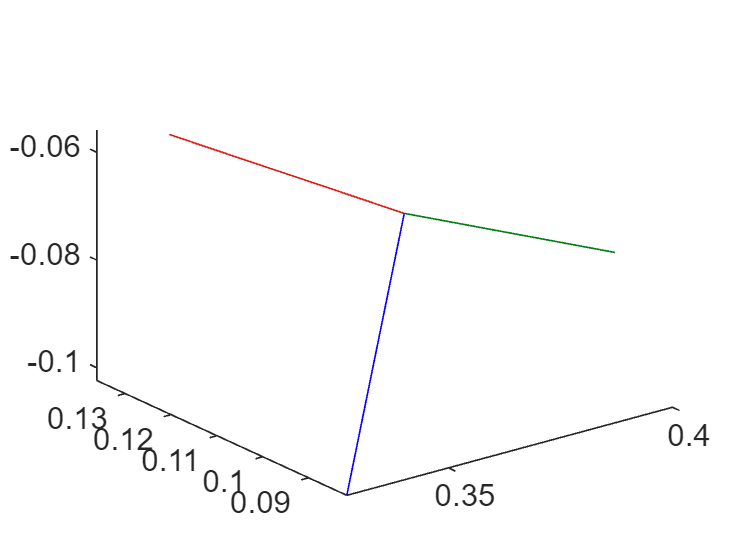

tagToBaseTestTform =    -0.0299    0.9352   -0.3529    0.3450
    0.9955   -0.0039   -0.0946    0.0864
   -0.0898   -0.3542   -0.9309   -0.0558
         0         0         0    1.0000


[tagToBaseTestTform]=Traj_ArucoMarker_2_tagPose(gen3,cameraParams,intrinsics,testPose_Radmat,frame)